fc = 4000;           % cutoff in Hz
fs = 48000;          % sampling rate
N = 101;             % filter length

h = lowpass_fir(fc, fs, N);               % design filter
x_low_filtered = conv(x, h, 'same');          % apply FIR filter via convolution

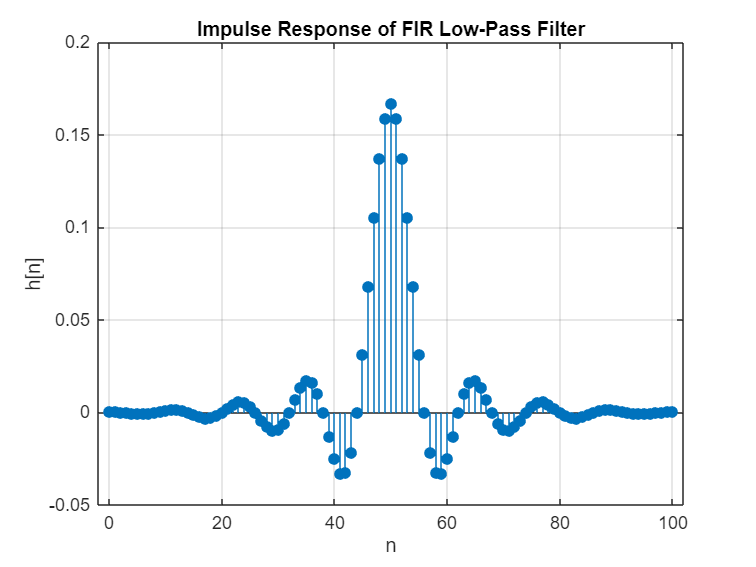

figure;
stem(0:N-1, h, 'filled');
xlabel('n'); ylabel('h[n]');
title('Impulse Response of FIR Low-Pass Filter');
grid on;

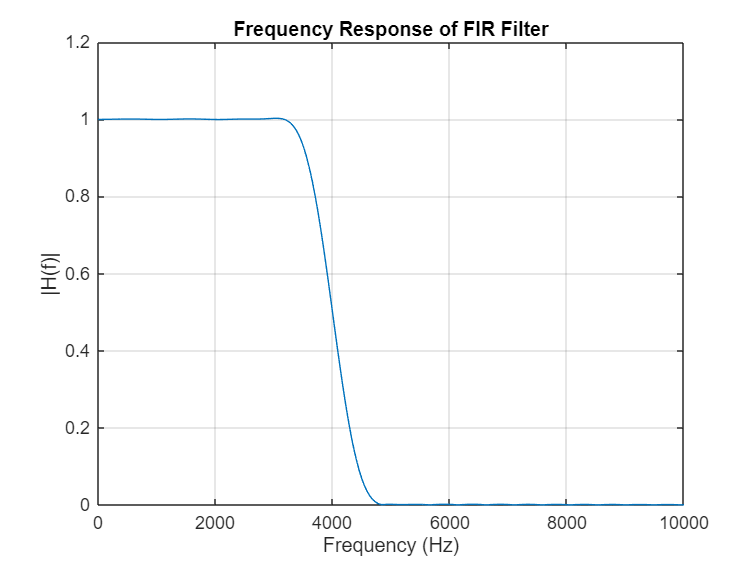

% Frequency axis (same as FFT)
N_fft = 1024;
f_axis = (0:N_fft-1) * fs / N_fft;

% Compute FFT of filter
H_f = abs(fft(h, N_fft));

% Plot
figure;
plot(f_axis, H_f);
xlabel('Frequency (Hz)');
ylabel('|H(f)|');
title('Frequency Response of FIR Filter');
xlim([0 10000]);
grid on;

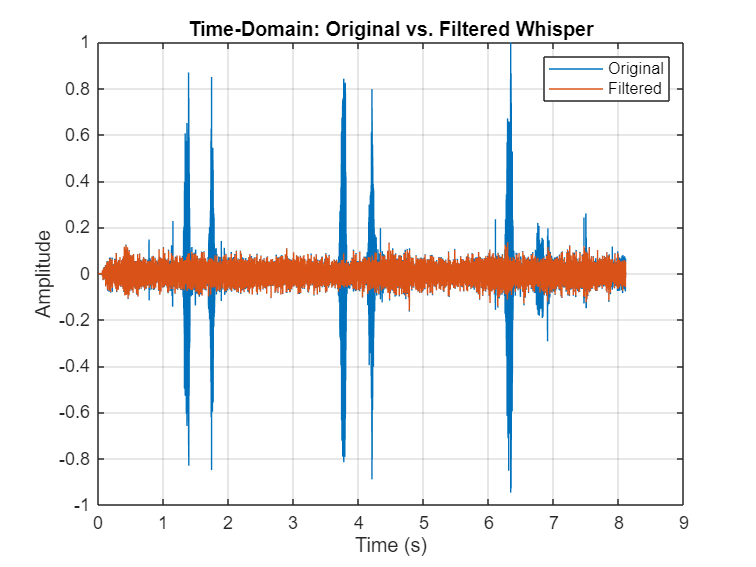

figure;
plot(t, x); hold on;
plot(t, x_low_filtered);
xlabel('Time (s)');
ylabel('Amplitude');
title('Time-Domain: Original vs. Filtered Whisper');
legend('Original','Filtered');
grid on;

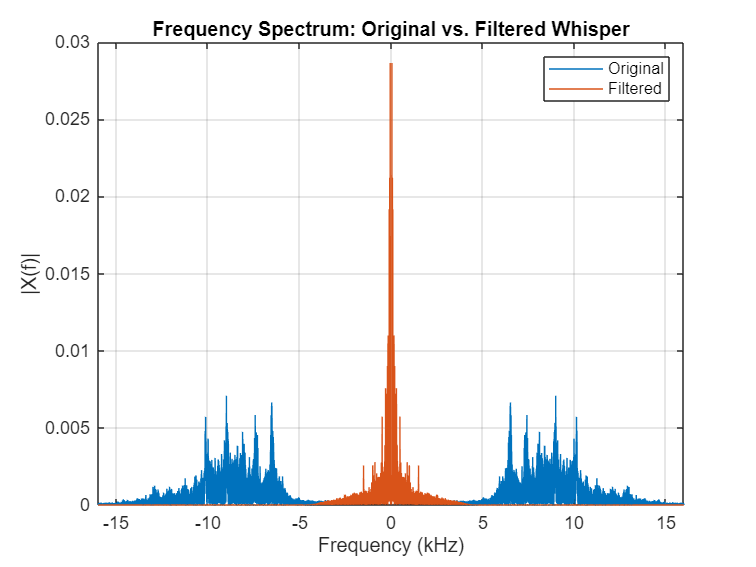

[~, xf_low_filtered, ~] = ftr(t, x_low_filtered, T, 'fft');

figure;
plot(f/1000, abs(xf)); hold on;
plot(f/1000, abs(xf_low_filtered));
xlabel('Frequency (kHz)');
ylabel('|X(f)|');
title('Frequency Spectrum: Original vs. Filtered Whisper');
legend('Original','Filtered');
xlim([-16, 16]);
grid on;

x_low_filtered = x_low_filtered / max(abs(x_low_filtered));
audiowrite('whisper_filtered_lowpass.wav', x_low_filtered, fs);